# `DEMO_02:`   4-bar linkage analysis - `dynamics`

Let's derive the Equations of Motion (EoM) of a 4bar linkage - see Figure_01 below.  We'll refer to the system **input** as $\theta$.  We'll look specifically at machines where the input crank can rotate a FULL revolution.

**Figure 01:  the 4bar linkage**

  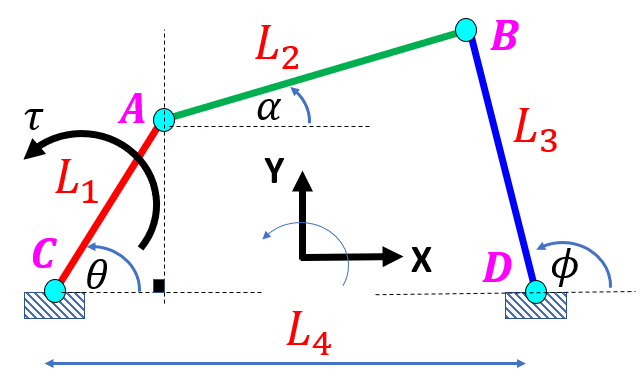

**REFs:**

- [https://en.wikipedia.org/wiki/Four-bar_linkage](https://en.wikipedia.org/wiki/Four-bar_linkage) 

- "A unified input-output analysis of a four bar linkags" - S.Bai, J.Angeles

- [https://www2.clarku.edu/faculty/djoyce/trig/identities.html](https://www2.clarku.edu/faculty/djoyce/trig/identities.html) 

- "Lagrangian Dynamic Formulation of a Four-Bar Mechanism with minimal Coordinates" - C.P. Tang

`Bradley Horton : 24-Jul-2019, bhorton@mathworks.com`

## Euler-Lagrange Technique for deriving equations of motion:

The Euler-Lagrange formula will be used to derive the equations of motion for our 4bar mechanism, and it has the form:

-  $\frac{d}{dt}\frac{\partial L}{\partial \dot{q}_k} - \frac{\partial L}{\partial q_k} = Q_k $     for     $k=1,2, \dots, n$

where  *n* is the DOF of the system, {$q_1, q_2, \dots, q_n$} is a set of generalized coordinates, {$Q_1, Q_2, \dots, Q_n$} is the set of generalized forces associated with those coordinates, and the Lagrangian:  ***L***** =  *****T***  ***-***  ***V****,* is defined as the difference between the kinetic and potential energy of the  *n-* DOF system. The Generalised forces can also be defined in terns of the non conservative forces and torques acting on the multibody system.  The formula for the generalised forces acting on the system is:

-    
$$Q_k = 
\sum_{i=1}^{Nf_{nc}}
\pmatrix{
\vec{F_i} \thinspace . \thinspace \frac{\partial \vec{v \thinspace _i}}{\partial \dot{q \thinspace}_k}
}  \enspace + \enspace
\sum_{j=1}^{N\tau_{nc}}
\pmatrix{
\vec {\tau_j} \thinspace . \thinspace \frac{\partial \vec{\omega \thinspace _j}}{\partial \dot{q \thinspace}_k}
}
$$


where:

- $Q_k$     :    is the generalised force associated with the $k^{th}$ generalised co-ordinate $q_k$

- $Nf_{nc}$ :    is the number of active NON conservative forces

- $N\tau_{nc}$:    is the number of active NON conservative TORQUES

- $\vec{v_i}$    :    is the velocity vector of the point associated with the applied force.

- $\vec{\omega_i}$   :    is the angular velocity about the point associated with the applied torque. 

**Note** : 

- For our system, we will choose  *q = {*$\theta$*}* 

- This is a 1 degree of freedom system, and as such there is a single 2nd order ODE that can be derived.

## Our derivation strategy:

In our kinematic analysis of the 4bar mechanism (see `DEMO_01_bh_4bar_analysis_kinematics.mlx` ) we derived relationships between $\theta ,\phi ,\textrm{and}\;\alpha$.  Specifically:

- 
$$\phi \left(L_1 ,L_2 ,L_3 ,L_4 ,\;\theta \right)\;\;\;\;\;\;\;\;\;\;\Longrightarrow \;\;\;\phi =g\left(L_1 ,L_2 ,L_3 ,L_4 ,\theta \right)$$


- 
$$\alpha \left(L_1 ,L_2 ,L_3 ,L_4 ,\;\theta ,\;\phi \right)\;\;\;\;\Longrightarrow \;\;\;\;\alpha =f\left(L_1 ,L_2 ,L_3 ,L_4 ,\theta \right)$$


In Appendix_01 of this script, we also derived the following:

- $\left\lbrack \begin{array}{c}
\dot{\phi} \\
\;\dot{\alpha} \;
\end{array}\right\rbrack \;\;=\;\;\;\left\lbrack \begin{array}{c}
\frac{\partial \phi }{\partial \theta }\\
\frac{\partial \alpha }{\partial \theta }
\end{array}\right\rbrack \ldotp \dot{\theta} \;\;$   where the Jacobians can be written as:

- 
$$\left\lbrack \begin{array}{c}
\frac{\partial \phi }{\partial \theta }\\
\frac{\partial \alpha }{\partial \theta }
\end{array}\right\rbrack \;\;=\;\;\;\frac{1}{L_3 \ldotp L_2 \ldotp \sin \left(\phi \right)\ldotp \cos \left(\alpha \right)-L_3 \ldotp L_2 \ldotp \cos \left(\phi \right)\ldotp \sin \left(\alpha \right)}\ldotp \left\lbrack \begin{array}{cc}
-L_2 \ldotp \cos \left(\alpha \right) & -L_2 \ldotp \sin \left(\alpha \right)\\
-L_3 \ldotp \cos \left(\phi \right) & -\;L_3 \ldotp \sin \left(\phi \right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{-L}_1 \ldotp \sin \left(\theta \right)\\
\;\;L_1 \ldotp \cos \left(\theta \right)
\end{array}\right\rbrack$$


So the Jacobians are:

- 
$$\;\;\frac{\partial \phi }{\partial \theta }\;\;=\;\;h\left(L_1 ,L_2 ,L_3 ,\;\;\theta ,\;\phi ,\alpha \right)$$


- 
$$\;\;\frac{\partial \alpha }{\partial \theta }\;\;=\;\;w\left(L_1 ,L_2 ,L_3 ,\;\;\theta ,\;\phi ,\alpha \right)$$


And the rates are:

- 
$$\;\;\dot{\phi} \;\;=\;\;n\left(L_1 ,L_2 ,L_3 ,\;\;\theta ,\;\phi ,\alpha ,\;\dot{\theta} \right)$$


- 
$$\;\;\dot{\alpha} \;\;=\;\;m\left(L_1 ,L_2 ,L_3 ,\;\;\theta ,\;\phi ,\alpha ,\;\dot{\theta} \right)$$


OK.  Our EoM derivation strategy is defined by the following steps:

**STEP_01:  define L**

We'll define our mechanical system Lagrangian as an expression of the form:

- 
$$L=E\left(\theta ,\phi ,\alpha ,\dot{\theta} ,\dot{\phi} ,\dot{\alpha} \right)$$


**STEP_02:  define a new L**

We'll utilise the expressions that we have for our rates $\dot{\phi}$ and $\dot{\alpha}$ 

- 
$$\;\;\dot{\phi} \;\;=\;\;n\left(L_1 ,L_2 ,L_3 ,\;\;\theta ,\;\phi ,\alpha ,\;\dot{\theta} \right)$$


- 
$$\;\;\dot{\alpha} \;\;=\;\;m\left(L_1 ,L_2 ,L_3 ,\;\;\theta ,\;\phi ,\alpha ,\;\dot{\theta} \right)$$


And substitute these expressions into $L$ to define a new Lagrangian of the form

- 
$$L_{\textrm{NEW}} =E\left(\theta ,\phi ,\alpha ,\dot{\theta} \right)$$


Note that the Lagrangian defined above only has derivative terms involving $\dot{\theta}$ .

**STEP_03:  define another new L**

We'll define 2 new symbolic functions:

- $\phi_f \left(\theta \right)$  and $\alpha_f \left(\theta \right)$

AND substitue these into $L_{\textrm{NEW}}$ (ie: replace the existing symbols $\phi$ and $\alpha$).  $L_{\textrm{NEW}}$ will then be a symbolic expression of the form:

- 
$$L_{\textrm{NEW}\;} =E\left(\;\;\theta ,\;\;\;\phi_f \left(\theta \right),{\;\;\;\alpha }_f \left(\theta \right),\;\;\;\dot{\theta} \right)\;\;=\;\;F\left(\theta ,\;\dot{\theta} \right)$$


We'll then create a symbolic function of the form:

- 
$$L_f \left(\theta ,\dot{\theta} \right)=\;L_{\textrm{NEW}}$$


The chain rule will then be applied when computing $\frac{\partial L_f }{\partial \theta }$.  For example:

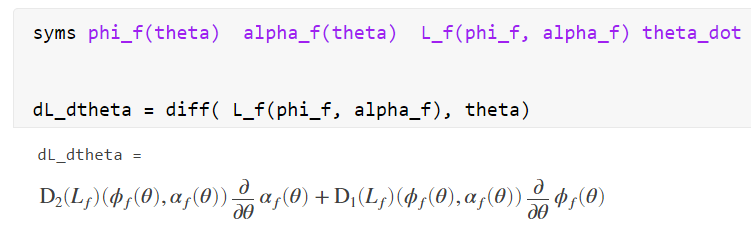

**STEP_04:  we'll compute **$\frac{\partial L_f }{\partial \theta }$

When we compute the partial derivative of L wrt $\theta$, we get an expression of the form:

- 
$$\frac{\partial L_f }{\partial \theta }\;\;=\;E\left(\theta ,\;\dot{\theta ,} \;\frac{\partial \phi }{\partial \theta },\;\frac{\partial \alpha }{\partial \theta }\right)$$


We'll then utilise our expressions for the Jacobians:

- 
$$\;\;\frac{\partial \phi }{\partial \theta }\;\;=\;\;h\left(L_1 ,L_2 ,L_3 ,\;\;\theta ,\;\phi ,\alpha \right)$$


- 
$$\;\;\frac{\partial \alpha }{\partial \theta }\;\;=\;\;w\left(L_1 ,L_2 ,L_3 ,\;\;\theta ,\;\phi ,\alpha \right)$$


And substitute these into $\frac{\partial L_f }{\partial \theta }$

- 
$$\frac{\partial L_f }{\partial \theta }\;\;=Z\left(\theta ,\;\dot{\theta ,} \;\;\phi ,\alpha \right)$$


**STEP_05:  we'll compute **$\frac{\partial L}{\partial \dot{\theta} }$

Recall the original expression for the Lagragian:

- 
$$L=E\left(\theta ,\phi ,\alpha ,\dot{\theta} ,\dot{\phi} ,\dot{\alpha} \right)$$


We utilise our expresions for $\dot{\phi}$ and $\dot{\alpha}$

- 
$$\;\;\dot{\phi} \;\;=\;\;n\left(L_1 ,L_2 ,L_3 ,\;\;\theta ,\;\phi ,\alpha ,\;\dot{\theta} \right)$$


- 
$$\;\;\dot{\alpha} \;\;=\;\;m\left(L_1 ,L_2 ,L_3 ,\;\;\theta ,\;\phi ,\alpha ,\;\dot{\theta} \right)$$


And substitute this into $L$

- 
$$L_{\textrm{NEW}} =E\left(\theta ,\phi ,\alpha ,\dot{\theta} \right)$$


**STEP_06:  we'll compute **$\frac{\partial L_{\textrm{NEW}} }{\partial \dot{\theta} }$

- 
$$\frac{\partial L_{\textrm{NEW}} }{\partial \dot{\theta} }=f\left(\theta ,\phi ,\alpha ,\dot{\theta} \right)$$


**STEP_07: we'll compute  **$\frac{d}{\textrm{dt}}\left(\frac{\partial L_{\textrm{NEW}} }{\partial \dot{\theta} }\right)$

To compute the time derivative of $\frac{\partial L_{\textrm{NEW}} }{\partial \dot{\theta} }$, we need ALL angular quantities specifed as functions of time.  So create some NEW symbolic variables:

- $\theta_t \left(t\right)$   and   $\phi_t \left(t\right)$  and   $\alpha_t \left(t\right)$  and  $\dot{\theta_t } \left(t\right)$

And substitue these into $\frac{\partial L_{\textrm{NEW}} }{\partial \dot{\theta} }$

- 
$$\frac{\partial L_{\textrm{NEW}} }{\partial \dot{\theta} }=\;\;f\left(\;\;\theta_t \left(t\right),\;\;\;\phi_t \left(t\right),\;\;\;\alpha_t \left(t\right),\;\;\;\theta_t \left(t\right),\;\;\;\dot{\theta_t } \left(t\right)\right)\;\;$$


And then we can compute the time derivative:

- 
$$\frac{d}{\textrm{dt}}\left(\frac{\partial L_{\textrm{NEW}} }{\partial \dot{\theta} }\right)\;=\;$$

$$B\left(\;\;\theta_t \left(t\right),\;\;\;\phi_t \left(t\right),\;\;\;\alpha_t \left(t\right),\;\;\;\theta_t \left(t\right),\;\;\;\dot{\theta_t } \left(t\right),\;\;\dot{\phi_t } \left(t\right),\;\;\dot{\alpha_t } \left(t\right),\;\;\;{\ddot{\theta} }_t \left(t\right)\;\;\right)$$


We then utilise our expressions for

- 
$$\;\;\dot{\phi} \;\;=\;\;n\left(L_1 ,L_2 ,L_3 ,\;\;\theta ,\;\phi ,\alpha ,\;\dot{\theta} \right)$$


- 
$$\;\;\dot{\alpha} \;\;=\;\;m\left(L_1 ,L_2 ,L_3 ,\;\;\theta ,\;\phi ,\alpha ,\;\dot{\theta} \right)$$


So that

- 
$$\frac{d}{\textrm{dt}}\left(\frac{\partial L_{\textrm{NEW}} }{\partial \dot{\theta} }\right)\;=\;$$

$$B\left(\;\;\theta_t \left(t\right),\;\;\;\phi_t \left(t\right),\;\;\;\alpha_t \left(t\right),\;\;\;\theta_t \left(t\right),\;\;\;\dot{\theta_t } \left(t\right),\;\;\;{\ddot{\theta} }_t \left(t\right)\;\;\right)$$


**STEP_08:  and now we're done**

We can now derive the 4bar equation of motion using:

- 
$$\frac{d}{\textrm{dt}}\left(\frac{\partial L_{\textrm{NEW}} }{\partial \dot{\theta} }\right)-\;\;\;\frac{\partial L_f }{\partial \theta }\;\;=\;\;\;\tau \;$$


Where $\tau$ is the torque applied at joint $C$.

# Deriving the Equations of Motion:

We'll use the Symbolic Math toolbox to help us implement our derivation strategy.  Consider the geometry parameters of a the 4bar mechanism shown below:

**Figure 01:  the 4bar linkage**

## Define the symbolic geometry parameters:

syms L_1   L_2   L_3  L_4           % link lengths
syms m_1   m_2   m_3                % link masses 
syms g                              % gravity
syms I_G1  I_G2  I_G3               % link Inertias about Z-axis through the centre of mass
syms theta      phi      alpha
syms theta_dot  phi_dot  alpha_dot 
syms theta_ddot
syms tau_1                          % the externally applied Torque at link CA

### Compute the Centre of mass position and the ${\left|v_G \right|}^2$ of each bar:

In Appendix_02 we derive the positions of the centre of mass for each link and the squared velocity magnitude of each link.

[x_G, y_G, vmag_SQ_G] = LOC_calc_CG_pos_vel_mag(L_1, L_2, L_3, L_4, ...
                                                      theta,     phi,     alpha, ...
                                                      theta_dot, phi_dot, alpha_dot )

$$x\_G = \left(\begin{array}{c} \frac{L_{1}\,\cos\left(\theta \right)}{2}\\ \frac{L_{2}\,\cos\left(\alpha \right)}{2}+L_{1}\,\cos\left(\theta \right)\\ L_{4}+\frac{L_{3}\,\cos\left(\varphi \right)}{2} \end{array}\right)$$

$$y\_G = \left(\begin{array}{c} \frac{L_{1}\,\sin\left(\theta \right)}{2}\\ \frac{L_{2}\,\sin\left(\alpha \right)}{2}+L_{1}\,\sin\left(\theta \right)\\ \frac{L_{3}\,\sin\left(\varphi \right)}{2} \end{array}\right)$$

$$vmag\_SQ\_G = \left(\begin{array}{c} \frac{{L_{1}}^{2}\,{\dot{\theta }}^{2}}{4}\\ {L_{1}}^{2}\,{\dot{\theta }}^{2}+\left(\sin\left(\alpha \right)\,\sin\left(\theta \right)+\cos\left(\alpha \right)\,\cos\left(\theta \right)\right)\,L_{1}\,L_{2}\,\dot{\alpha }\,\dot{\theta }+\frac{{L_{2}}^{2}\,{\dot{\alpha }}^{2}}{4}\\ \frac{{L_{3}}^{2}\,{\dot{\varphi }}^{2}}{4} \end{array}\right)$$

### Compute the Kinetic energy of each bar:

For ***each*** bar/link we can write the kinetic energy as:

- 
$$\textrm{KE}\;\;=\;\;\frac{1}{2}\ldotp m\ldotp v_G^T \;\ldotp v_G \;\;+\;\;\frac{1}{2}\ldotp I_G \ldotp \omega^T \ldotp \omega$$


where:

- $m\;$is the mass of the bar

- $v_G$ is the velocity vector of the bar's centre of mass

- $I_G$ is the moment of inertia of the bar about the bar's centre of mass

- $\omega_G$ is the angular velocity vector of the bar

The translational component:

KE_trans = (1/2)*m_1*vmag_SQ_G(1)  +  (1/2)*m_2*vmag_SQ_G(2) +  (1/2)*m_3*vmag_SQ_G(3);

The rotational component:

KE_rot   = (1/2)*I_G1*(theta_dot^2)  +  (1/2)*I_G2*(alpha_dot^2) +  (1/2)*I_G3*(phi_dot^2);

The Total KE:

KE     = KE_trans + KE_rot

$$KE = \frac{m_{2}\,\left({L_{1}}^{2}\,{\dot{\theta }}^{2}+\left(\sin\left(\alpha \right)\,\sin\left(\theta \right)+\cos\left(\alpha \right)\,\cos\left(\theta \right)\right)\,L_{1}\,L_{2}\,\dot{\alpha }\,\dot{\theta }+\frac{{L_{2}}^{2}\,{\dot{\alpha }}^{2}}{4}\right)}{2}+\frac{I_{\mathrm{G2}}\,{\dot{\alpha }}^{2}}{2}+\frac{I_{\mathrm{G3}}\,{\dot{\varphi }}^{2}}{2}+\frac{I_{\mathrm{G1}}\,{\dot{\theta }}^{2}}{2}+\frac{{L_{3}}^{2}\,m_{3}\,{\dot{\varphi }}^{2}}{8}+\frac{{L_{1}}^{2}\,m_{1}\,{\dot{\theta }}^{2}}{8}$$

### Compute the potential energy of each bar:

PE = m_1*g*y_G(1)  +  m_2*g*y_G(2)  +  m_3*g*y_G(3) 

$$PE = g\,m_{2}\,\left(\frac{L_{2}\,\sin\left(\alpha \right)}{2}+L_{1}\,\sin\left(\theta \right)\right)+\frac{L_{3}\,g\,m_{3}\,\sin\left(\varphi \right)}{2}+\frac{L_{1}\,g\,m_{1}\,\sin\left(\theta \right)}{2}$$

### Compute the system Lagrangian as an EXPRESSION:

L_lag_orig = KE - PE

$$L\_lag\_orig = \frac{m_{2}\,\left({L_{1}}^{2}\,{\dot{\theta }}^{2}+\left(\sin\left(\alpha \right)\,\sin\left(\theta \right)+\cos\left(\alpha \right)\,\cos\left(\theta \right)\right)\,L_{1}\,L_{2}\,\dot{\alpha }\,\dot{\theta }+\frac{{L_{2}}^{2}\,{\dot{\alpha }}^{2}}{4}\right)}{2}+\frac{I_{\mathrm{G2}}\,{\dot{\alpha }}^{2}}{2}+\frac{I_{\mathrm{G3}}\,{\dot{\varphi }}^{2}}{2}+\frac{I_{\mathrm{G1}}\,{\dot{\theta }}^{2}}{2}+\frac{{L_{3}}^{2}\,m_{3}\,{\dot{\varphi }}^{2}}{8}+\frac{{L_{1}}^{2}\,m_{1}\,{\dot{\theta }}^{2}}{8}-g\,m_{2}\,\left(\frac{L_{2}\,\sin\left(\alpha \right)}{2}+L_{1}\,\sin\left(\theta \right)\right)-\frac{L_{3}\,g\,m_{3}\,\sin\left(\varphi \right)}{2}-\frac{L_{1}\,g\,m_{1}\,\sin\left(\theta \right)}{2}$$

***Note the symbolic variables that this Lagrangian expression contains:***

symvar(L_lag_orig)

$$ans = \left(\begin{array}{cccccccccccccccc} I_{\mathrm{G1}} & I_{\mathrm{G2}} & I_{\mathrm{G3}} & L_{1} & L_{2} & L_{3} & \alpha & \dot{\alpha } & g & m_{1} & m_{2} & m_{3} & \varphi & \dot{\varphi } & \theta & \dot{\theta } \end{array}\right)$$

### Compute the rates and Jacobians for $\phi$ and $\alpha$ :

See Appendix_01 for the local function that computes these.

[E_phi_dot, E_alpha_dot, E_dphi_dtheta, E_dalpha_dtheta] = ...
       LOC_calc_phi_alpha_rates_and_jacobs(L_1, L_2, L_3, theta,     phi,     alpha, theta_dot)

$$E\_phi\_dot = \dot{\theta }\,\left(\frac{L_{1}\,\cos\left(\alpha \right)\,\sin\left(\theta \right)}{L_{3}\,\left(\cos\left(\alpha \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\alpha \right)\right)}-\frac{L_{1}\,\sin\left(\alpha \right)\,\cos\left(\theta \right)}{L_{3}\,\left(\cos\left(\alpha \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\alpha \right)\right)}\right)$$

$$E\_alpha\_dot = \dot{\theta }\,\left(\frac{L_{1}\,\cos\left(\varphi \right)\,\sin\left(\theta \right)}{L_{2}\,\left(\cos\left(\alpha \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\alpha \right)\right)}-\frac{L_{1}\,\cos\left(\theta \right)\,\sin\left(\varphi \right)}{L_{2}\,\left(\cos\left(\alpha \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\alpha \right)\right)}\right)$$

$$E\_dphi\_dtheta = \frac{L_{1}\,\cos\left(\alpha \right)\,\sin\left(\theta \right)}{L_{3}\,\left(\cos\left(\alpha \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\alpha \right)\right)}-\frac{L_{1}\,\sin\left(\alpha \right)\,\cos\left(\theta \right)}{L_{3}\,\left(\cos\left(\alpha \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\alpha \right)\right)}$$

$$E\_dalpha\_dtheta = \frac{L_{1}\,\cos\left(\varphi \right)\,\sin\left(\theta \right)}{L_{2}\,\left(\cos\left(\alpha \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\alpha \right)\right)}-\frac{L_{1}\,\cos\left(\theta \right)\,\sin\left(\varphi \right)}{L_{2}\,\left(\cos\left(\alpha \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\alpha \right)\right)}$$

### Create a new Lagrangian EXPRESSION - $L\left(\theta ,\phi ,\alpha ,\dot{\theta} \right)$

Now substitute the expressions for $\dot{\phi}$ and $\dot{\alpha}$ into our Lagrangian:

L_new = subs(L_lag_orig, [phi_dot, alpha_dot], [E_phi_dot, E_alpha_dot])   

***Note the symbolic variables that this Lagrangian expression contains:***

symvar(L_new)

$$ans = \left(\begin{array}{cccccccccccccc} I_{\mathrm{G1}} & I_{\mathrm{G2}} & I_{\mathrm{G3}} & L_{1} & L_{2} & L_{3} & \alpha & g & m_{1} & m_{2} & m_{3} & \varphi & \theta & \dot{\theta } \end{array}\right)$$

So if we focus ONLY on the angular variables, we see that our Lagrangian is an **expression** containing:

- 
$$L\left(\theta ,\phi ,\alpha ,\dot{\theta} \right)$$


### Define the dependent variables - $\phi_f \left(\theta \right)$, $\alpha_f \left(\theta \right)$

Next create some NEW variables, specifically:

- $\phi_f \left(\theta \right)$   and   $\alpha_f \left(\theta \right)$

syms phi_f(theta)  alpha_f(theta)  L_f(theta, theta_dot)

Create a new expression for the Lagrangian that uses these new variables

L_new = subs(L_new, [phi, alpha], [phi_f(theta), alpha_f(theta)])

### Define the Lagrangian as a symbolic FUNCTION:

Now specify a Lagrangian function:

- 
$$L\left(\theta ,\dot{\theta} \right)$$


L_f(theta, theta_dot) = L_new

***Note the symbolic variables contained in this symbolic ******function******:***

symvar(L_f)

$$ans = \left(\begin{array}{cccccccccccc} \theta & \dot{\theta } & I_{\mathrm{G1}} & I_{\mathrm{G2}} & I_{\mathrm{G3}} & L_{1} & L_{2} & L_{3} & g & m_{1} & m_{2} & m_{3} \end{array}\right)$$

### Lagrangian computation - part 1  $\frac{\partial L}{\partial \theta }$

dL_dtheta = diff( L_f(theta, theta_dot), theta)


whos dL_dtheta

  Name           Size            Bytes  Class    Attributes

  dL_dtheta      1x1                 8  sym                



***Note the symbolic variables contained in this:***

symvar(dL_dtheta)

$$ans = \left(\begin{array}{ccccccccccc} I_{\mathrm{G2}} & I_{\mathrm{G3}} & L_{1} & L_{2} & L_{3} & g & m_{1} & m_{2} & m_{3} & \theta & \dot{\theta } \end{array}\right)$$

Now substitute our Jacobians into $\frac{\partial L}{\partial \theta }$:

- $\frac{\partial \phi }{\partial \theta }\;$ and    $\frac{\partial \alpha }{\partial \theta }$

dL_dtheta = subs(dL_dtheta, [diff(phi_f(theta),theta),  diff(alpha_f(theta), theta)], ...
                            [          E_dphi_dtheta ,             E_dalpha_dtheta]);
                        
dL_dtheta = subs(dL_dtheta, [ phi_f(theta), alpha_f(theta) ] , [phi, alpha]);    

***Note the symbolic variables contained in this symbolic expression:***

- 
$$\frac{\partial L}{\partial \theta }=f\left(\theta ,\phi ,\alpha ,\dot{\theta} \right)$$


symvar(dL_dtheta)

$$ans = \left(\begin{array}{ccccccccccccc} I_{\mathrm{G2}} & I_{\mathrm{G3}} & L_{1} & L_{2} & L_{3} & \alpha & g & m_{1} & m_{2} & m_{3} & \varphi & \theta & \dot{\theta } \end{array}\right)$$

### Lagrangian computation - part 2  $\frac{\partial L}{\partial \dot{\theta} }$

Revisit our ORIGINAL Lagrangian expression `L_lag_orig`, and substitute in our expressions for $\dot{\phi}$ and $\dot{\alpha}$

- 
$$\left\lbrack \begin{array}{c}
\dot{\phi} \\
\dot{\alpha} 
\end{array}\right\rbrack \;\;=\;\;\;\left\lbrack \begin{array}{c}
\frac{\partial \phi }{\partial \theta }\\
\frac{\partial \alpha }{\partial \theta }
\end{array}\right\rbrack \ldotp \dot{\theta}$$


L_new = subs(L_lag_orig, [phi_dot, alpha_dot], [E_phi_dot, E_alpha_dot]);   

Now compute the derivative $\frac{\partial L}{\partial \dot{\theta} }$  :

  dL_dtheta_dot = diff(L_new, theta_dot)         

***Note the symbolic variables contained in this symbolic expression:***

- 
$$\frac{\partial L}{\partial \dot{\theta} }=f\left(\theta ,\phi ,\alpha ,\dot{\theta} \right)$$


symvar(dL_dtheta_dot)

$$ans = \left(\begin{array}{ccccccccccccc} I_{\mathrm{G1}} & I_{\mathrm{G2}} & I_{\mathrm{G3}} & L_{1} & L_{2} & L_{3} & \alpha & m_{1} & m_{2} & m_{3} & \varphi & \theta & \dot{\theta } \end{array}\right)$$

### Lagrangian computation - part 3  $\frac{d}{\textrm{dt}}\left(\frac{\partial L}{\partial \dot{\theta} }\right)$

To compute the time derivative of $\frac{\partial L}{\partial \dot{\theta} }$, we need ALL angular quantities specifed as functions of time.  So create some NEW symbolic variables:

- $\theta_t \left(t\right)$   and   $\phi_t \left(t\right)$  and   $\alpha_t \left(t\right)$

syms theta_t(t) phi_t(t)  alpha_t(t)      
% new_dL_dtheta_dot = subs(dL_dtheta_dot, [theta,        phi,      alpha,      theta_dot], ...
%                                         [theta_t(t),   phi_t(t), alpha_t(t), diff(theta_t(t),t)] )
new_dL_dtheta_dot = subs(dL_dtheta_dot, [theta_dot,          theta,        phi,      alpha,      ], ...
                                        [diff(theta_t(t),t), theta_t(t),   phi_t(t), alpha_t(t)] )

Now compute the time derivative:

tder_new_dL_dtheta_dot = diff(new_dL_dtheta_dot, t)

Now substitute back our original SYMBOLS, ie:

- `diff(`$\theta_t \left(t\right)$`, t, 2)   `$\Longrightarrow \;\;\;$$\ddot{\theta}$

- `diff(`$\theta_t \left(t\right)$`,t)   `$\Longrightarrow \;\;\;$$\dot{\theta}$

- `diff(`$\phi_t \left(t\right)$`,t)   `$\Longrightarrow \;\;\;$$\dot{\phi}$

- `diff(`$\alpha_t \left(t\right)$`,t)   `$\Longrightarrow \;\;\;$$\dot{\alpha}$

tder_new_dL_dtheta_dot = subs(  tder_new_dL_dtheta_dot, ...
                               [diff(theta_t(t),t,2),  diff(theta_t(t),t),  diff(phi_t(t),t),  diff(alpha_t(t),t)], ...
                               [          theta_ddot,           theta_dot,        E_phi_dot,         E_alpha_dot] );

***Note the symbolic variables contained in this symbolic expression:***

- 
$$\frac{d}{\textrm{dt}}\left(\frac{\partial L}{\partial \dot{\theta} }\right)=f\left(\theta ,\phi ,\alpha ,\dot{\theta} \right)$$


symvar(tder_new_dL_dtheta_dot)

$$ans = \left(\begin{array}{ccccccccccccccc} I_{\mathrm{G1}} & I_{\mathrm{G2}} & I_{\mathrm{G3}} & L_{1} & L_{2} & L_{3} & \alpha & m_{1} & m_{2} & m_{3} & \varphi & t & \theta & \ddot{\theta } & \dot{\theta } \end{array}\right)$$

Now replace  $\theta_t \left(t\right)$,$\phi_t \left(t\right)$, $\alpha_t \left(t\right)$ with $\theta ,\phi ,\alpha$

 tder_new_dL_dtheta_dot = subs(tder_new_dL_dtheta_dot, ...
                               [theta_t(t), phi_t(t), alpha_t(t)], ...
                               [theta, phi, alpha])     

***Note the symbolic variables contained in this symbolic expression:***

- 
$$\frac{d}{\textrm{dt}}\left(\frac{\partial L}{\partial \dot{\theta} }\right)=f\left(\theta ,\phi ,\alpha ,\dot{\theta} ,\;\ddot{\theta} \right)$$


symvar(tder_new_dL_dtheta_dot)                           

$$ans = \left(\begin{array}{cccccccccccccc} I_{\mathrm{G1}} & I_{\mathrm{G2}} & I_{\mathrm{G3}} & L_{1} & L_{2} & L_{3} & \alpha & m_{1} & m_{2} & m_{3} & \varphi & \theta & \ddot{\theta } & \dot{\theta } \end{array}\right)$$

### Lagrangian computation - part 4     $\tau_1 =\;\frac{d}{\textrm{dt}}\left(\frac{\partial L}{\partial \dot{\theta} }\right)-\frac{\partial L}{\partial \theta }\;$

EQ_system = tau_1 == tder_new_dL_dtheta_dot - dL_dtheta      

### Now solve for $\ddot{\theta}$

the_sol_theta_dot_dot = solve(EQ_system, theta_ddot)     

### Convert $\ddot{\theta}$ into a Simulink block

To use/solve these derived equations of motion we'll create a MATLAB Function block that can be used inside Simulink:

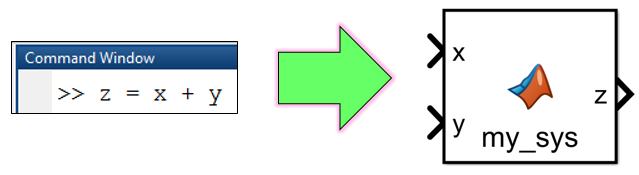

Now create the MATLAB function blocks for Simulink:

tf_i_should_create_SL_block = true;

if(true==tf_i_should_create_SL_block)
    MODEL_NAME = 'bh_tmp_model_for_lagr';
    if(4==exist(MODEL_NAME))
        close_system(MODEL_NAME, 0);
        delete(MODEL_NAME);
    end
    new_system(MODEL_NAME)
    open_system(MODEL_NAME)   
                          
    % Put BOTH equations into one block 
    BLOCK_NAME = [MODEL_NAME,'/THE_THETA_SYS_DD'];
    matlabFunctionBlock( BLOCK_NAME, the_sol_theta_dot_dot, ...
                         'Optimize', false, ...
                         'Outputs', {'theta_DD'}   );  
                     
                            % make the block YELLOW                   
   set_param( BLOCK_NAME,'BackgroundColor', '[0.996078, 1.000000, 0.705882]');     
end

# Next steps - a dynamic model in **Simulink**

Having derived the equations of motion for the 4bar mechanism, the next sensible step is to solve these equations ... and we'll use Simulink to do that.

So NEXT steps will be

- Open the script called `DEMO_03b_bh_4bar_DYN_sim.mlx`

- Run the script and explore the Simulink model `bh_4bar_model_DYN.slx`

- Run the Simulink model `bh_4bar_model_DYN.slx`

We have implemented our hand derivation in the subsystem called` Hand_model`

  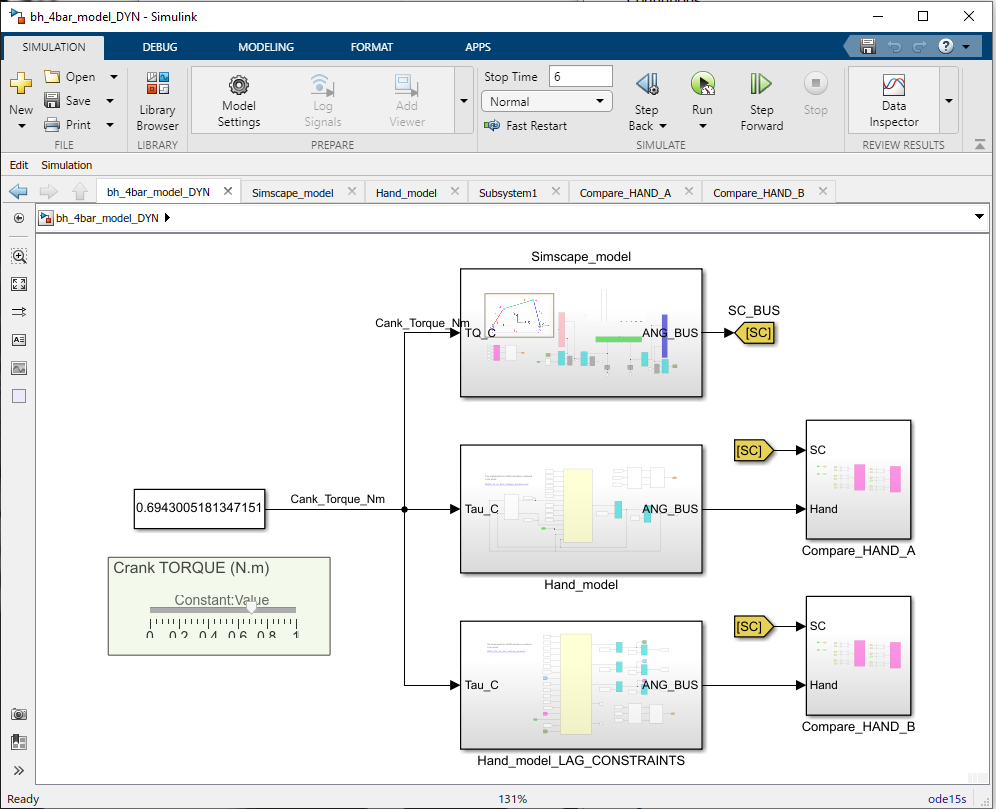       

# **Local Functions only beyond this point**

# Appendix 01 - The Jacobians

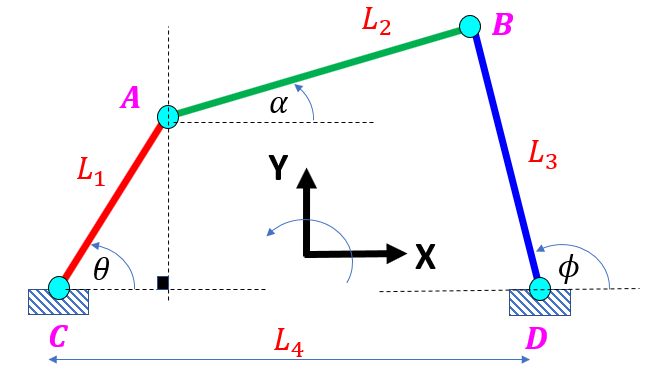

From our earlier Kinematic analysis we derived the relationships:

- $\;L_2 \ldotp \cos \left(\alpha \right)\;\;=L_4 \;-\;\;L_1 \ldotp \cos \left(\theta \right)\;+\;\;\;L_3 \ldotp \cos \left(\phi \right)$  ` .....    EQ_1`

- $L_1 \ldotp \cos \left(\theta \right)\;\;=L_4 \;-\;\;L_2 \ldotp \cos \left(\alpha \right)\;+\;\;\;L_3 \ldotp \cos \left(\phi \right)$     `.....    EQ_1b`

And

- $L_2 \ldotp \sin \left(\alpha \right)\;\;=\;\;\;\;L_3 \ldotp \sin \left(\phi \right)\;\;-\;\;L_1 \ldotp \sin \left(\theta \right)\;$    `.....    EQ_2`

- $L_1 \ldotp \sin \left(\theta \right)\;\;=\;\;\;\;L_3 \ldotp \sin \left(\phi \right)\;\;-\;L_2 \ldotp \sin \left(\alpha \right)\;$     `.....    EQ_2b`

Now take the time derivative of `EQ_1b` and `EQ_2b` and we get :

- ${-L}_1 \ldotp \sin \left(\theta \right)\ldotp \dot{\theta} \;\;\;\;=\;\;L_2 \ldotp \sin \left(\alpha \right)\ldotp \dot{\alpha} \;\;\;-\;L_3 \ldotp \sin \left(\phi \right)\ldotp \dot{\phi}$      `.....    EQ_1c`

-    $L_1 \ldotp \cos \left(\theta \right)\ldotp \dot{\theta} \;\;\;=\;\;\;\;L_3 \ldotp \cos \left(\phi \right)\ldotp \dot{\phi} \;\;-L_2 \ldotp \cos \left(\alpha \right)\ldotp \dot{\alpha} \;$     `.....    EQ_2c`

If we rewrite these last 2 equations in matrix form, we get:

- 
$$\left\lbrack \begin{array}{c}
{-L}_1 \ldotp \sin \left(\theta \right)\\
\;\;L_1 \ldotp \cos \left(\theta \right)
\end{array}\right\rbrack \ldotp \dot{\theta} \;\;=\;\;\left\lbrack \begin{array}{cc}
-\;L_3 \ldotp \sin \left(\phi \right) & L_2 \ldotp \sin \left(\alpha \right)\\
L_3 \ldotp \cos \left(\phi \right) & -L_2 \ldotp \cos \left(\alpha \right)
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
\dot{\phi} \\
\;\dot{\alpha \;} 
\end{array}\right\rbrack$$


Which has the general shape:

- $\left\lbrack \begin{array}{c}
f\left(\theta \right)
\end{array}\right\rbrack \ldotp \dot{\theta} \;=\;\left\lbrack \begin{array}{c}
A\left(\phi ,\alpha \right)
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
\dot{\phi} \\
\dot{\alpha} 
\end{array}\right\rbrack$  which can then be rearranged to:

- 
$$\left\lbrack \begin{array}{c}
\dot{\phi} \\
\;\dot{\alpha} \;
\end{array}\right\rbrack =\;\;{\left\lbrack \begin{array}{c}
A\left(\phi ,\alpha \right)
\end{array}\right\rbrack }^{-1} \;\ldotp \;\left\lbrack \begin{array}{c}
f\left(\theta \right)
\end{array}\right\rbrack \;\ldotp \dot{\theta} \;$$


So doing the rearrangement and the matrix inverse, leads to:

- $\left\lbrack \begin{array}{c}
\dot{\phi} \\
\dot{\alpha} 
\end{array}\right\rbrack \;\;=\;\;\;\frac{1}{L_3 \ldotp L_2 \ldotp \sin \left(\phi \right)\ldotp \cos \left(\alpha \right)-L_3 \ldotp L_2 \ldotp \cos \left(\phi \right)\ldotp \sin \left(\alpha \right)}\ldotp \left\lbrack \begin{array}{cc}
-L_2 \ldotp \cos \left(\alpha \right) & -L_2 \ldotp \sin \left(\alpha \right)\\
-L_3 \ldotp \cos \left(\phi \right) & -\;L_3 \ldotp \sin \left(\phi \right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{-L}_1 \ldotp \sin \left(\theta \right)\\
\;\;L_1 \ldotp \cos \left(\theta \right)
\end{array}\right\rbrack \ldotp \dot{\theta} \;\;\;\;$   `..... EQ_3`

The big result summarised in `EQ_3` are the Jacobians.  Recall that our kinematic analysis allowed us to write:

- 
$$\phi =f\left(\theta \right)$$


- 
$$\alpha =g\left(\theta \right)$$


Therefore:

- 
$$\dot{\phi} \;=\;\frac{d\phi }{\textrm{dt}}\;=\;\frac{\partial \phi }{\partial \theta }\ldotp \frac{d\theta }{\textrm{dt}}\;\;=\;\;\frac{\partial \phi }{\partial \theta }\ldotp \dot{\theta}$$


- 
$$\dot{\alpha} \;=\;\frac{d\alpha }{\textrm{dt}}\;=\;\frac{\partial \alpha }{\partial \theta }\ldotp \frac{d\theta }{\textrm{dt}}\;\;\;\;=\;\;\frac{\partial \alpha }{\partial \theta }\ldotp \dot{\theta}$$


So `EQ_3` can also be written as:

- 
$$\left\lbrack \begin{array}{c}
\dot{\phi} \\
\dot{\alpha} 
\end{array}\right\rbrack \;\;=\;\;\;\left\lbrack \begin{array}{c}
\frac{\partial \phi }{\partial \theta }\\
\frac{\partial \alpha }{\partial \theta }
\end{array}\right\rbrack \ldotp \dot{\theta} \;\;$$


where the Jacobians can be written as:

- 
$$\left\lbrack \begin{array}{c}
\frac{\partial \phi }{\partial \theta }\\
\frac{\partial \alpha }{\partial \theta }
\end{array}\right\rbrack \;\;=\;\;\;\frac{1}{L_3 \ldotp L_2 \ldotp \sin \left(\phi \right)\ldotp \cos \left(\alpha \right)-L_3 \ldotp L_2 \ldotp \cos \left(\phi \right)\ldotp \sin \left(\alpha \right)}\ldotp \left\lbrack \begin{array}{cc}
-L_2 \ldotp \cos \left(\alpha \right) & -L_2 \ldotp \sin \left(\alpha \right)\\
-L_3 \ldotp \cos \left(\phi \right) & -\;L_3 \ldotp \sin \left(\phi \right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{-L}_1 \ldotp \sin \left(\theta \right)\\
\;\;L_1 \ldotp \cos \left(\theta \right)
\end{array}\right\rbrack$$


function [E_phi_dot, E_alpha_dot, E_dphi_dtheta, E_dalpha_dtheta] = ...
       LOC_calc_phi_alpha_rates_and_jacobs(s_L1, s_L2, s_L3, s_theta, s_phi, s_alpha, s_theta_dot)

   k = 1/( s_L3*s_L2*(sin(s_phi)*cos(s_alpha)   -  cos(s_phi)*sin(s_alpha))  );
       
   tmp_A      =   [-s_L2*cos(s_alpha), -s_L2*sin(s_alpha);
                   -s_L3*cos(s_phi),   -s_L3*sin(s_phi);   ];
               
   tmp_B      =   [ -s_L1*sin(s_theta);
                     s_L1*cos(s_theta); ];
   
   the_jacobs    = k * tmp_A * tmp_B;
   
   E_dphi_dtheta   =  the_jacobs(1);
   E_dalpha_dtheta =  the_jacobs(2);   

   E_phi_dot       = E_dphi_dtheta   * s_theta_dot;
   E_alpha_dot     = E_dalpha_dtheta * s_theta_dot;

end

# Appendix 02 - Center of Mass positions and velocities

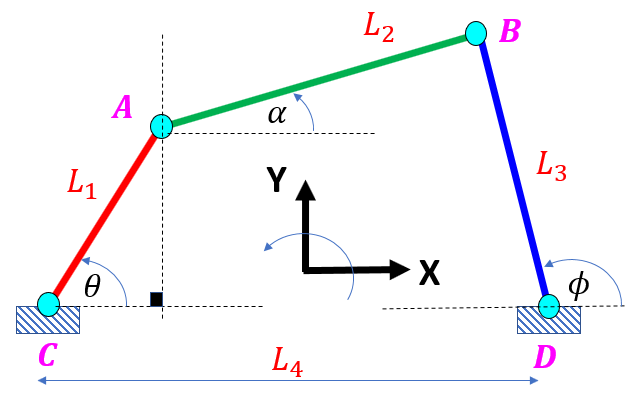

For **Bar_1** we have:

- 
$$x_{\textrm{G1}} =\frac{L_1 }{2}\ldotp \cos \left(\theta \right)\;\;\;\;\;\Longrightarrow \;\;\;{\dot{x} }_{\textrm{G1}} =\;\frac{{-L}_1 }{2}\ldotp \sin \left(\theta \right)\ldotp \dot{\theta}$$


- 
$$y_{\textrm{G1}} =\frac{L_1 }{2}\ldotp \sin \left(\theta \right)\;\;\;\;\;\Longrightarrow \;\;\;\;{\dot{y} }_{\textrm{G1}} =\;\frac{L_1 }{2}\ldotp \cos \left(\theta \right)\ldotp \dot{\theta} \;$$


- 
$$v_{\textrm{G1}}^T \ldotp v_{\textrm{G1}} =\frac{L_1^2 }{4}\ldotp {\left(\dot{\theta} \right)}^2$$


For **Bar_3** we have:

- 
$$x_{\textrm{G3}} =\;\;L_4 \;\;+\;\;\frac{L_3 }{2}\ldotp \cos \left(\phi \right)\;\;\;\;\;\Longrightarrow \;\;\;{\dot{x} }_{\textrm{G3}} =\;\frac{{-L}_3 }{2}\ldotp \sin \left(\phi \right)\ldotp \dot{\phi}$$


- 
$$y_{\textrm{G3}} =\frac{L_3 }{2}\ldotp \sin \left(\phi \right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Longrightarrow \;\;\;\;{\dot{y} }_{\textrm{G3}} =\;\frac{L_3 }{2}\ldotp \cos \left(\phi \right)\ldotp \dot{\phi} \;$$


- 
$$v_{\textrm{G3}}^T \ldotp v_{\textrm{G3}} =\frac{L_3^2 }{4}\ldotp {\left(\dot{\phi} \right)}^2$$


For **Bar_2** we have:

- 
$$x_{\textrm{G2}} =L_1 \ldotp \cos \left(\theta \right)\;+\;\frac{L_2 }{2}\ldotp \cos \left(\alpha \right)\;\;\;\;\;\Longrightarrow \;\;\;\;\;\;\;{\dot{x} }_{\textrm{G2}} =\;\;{-L}_1 \ldotp \sin \left(\theta \right)\ldotp \dot{\theta} \;\;\;\;+\;\frac{{-L}_2 }{2}\ldotp \sin \left(\alpha \right)\ldotp \dot{\alpha}$$


- 
$$y_{\textrm{G2}} =L_1 \ldotp \sin \left(\theta \right)\;+\;\frac{L_2 }{2}\ldotp \sin \left(\alpha \right)\;\;\;\;\;\Longrightarrow \;\;\;\;\;\;\;{\dot{y} }_{\textrm{G2}} =\;\;L_1 \ldotp \cos \left(\theta \right)\ldotp \dot{\theta} \;\;\;\;+\;\frac{L_2 }{2}\ldotp \cos \left(\alpha \right)\ldotp \dot{\alpha}$$


- 
$$v_{\textrm{G2}}^T \ldotp v_{\textrm{G2}} \;\;=\;L_1^2 \ldotp {\left(\dot{\theta} \right)}^2 \;\;+\;\;\;\frac{L_2^2 }{4}\ldotp {\left(\dot{\alpha} \right)}^2 \;\;\;+\;\;\;\;L_1 \ldotp L_2 \ldotp \dot{\theta} \ldotp \dot{\alpha} \ldotp \left(\sin \left(\theta \right)\ldotp \sin \left(\alpha \right)\;\;+\;\cos \left(\theta \right)\ldotp \cos \left(\alpha \right)\right)$$


function [x_G, y_G, vmag_SQ_G] = LOC_calc_CG_pos_vel_mag(s_L1, s_L2, s_L3, s_L4, ...
                                                      s_theta,     s_phi,     s_alpha, ...
                                                      s_theta_dot, s_phi_dot, s_alpha_dot )

   x_G(1,1) =        (s_L1/2)*cos(s_theta);
   x_G(3,1) = s_L4 + (s_L3/2)*cos(s_phi);
   x_G(2,1) =          (s_L1)*cos(s_theta)   +  (s_L2/2)*cos(s_alpha);   
   
   y_G(1,1) =        (s_L1/2)*sin(s_theta);
   y_G(3,1) =        (s_L3/2)*sin(s_phi);
   y_G(2,1) =          (s_L1)*sin(s_theta)   +  (s_L2/2)*sin(s_alpha);      

   vmag_SQ_G(1,1) = (s_theta_dot * s_L1/2)^2 ;
   vmag_SQ_G(3,1) = (s_phi_dot   * s_L3/2)^2 ;
   vmag_SQ_G(2,1) = (s_theta_dot * s_L1)^2   +  (s_alpha_dot * s_L2/2)^2  +  ...
                  s_L1*s_L2*s_theta_dot*s_alpha_dot*( sin(s_theta)*sin(s_alpha) +  cos(s_theta)*cos(s_alpha) );
   
end